# **Thermal Hydraulics Assignment 2, Q2**

## 0. Setup

Code initiation

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

## 1.  Problem Statement

Consider a slab with an initial temperature profile as shown below. Calculate the unsteady temperature profiles numerically as done in class, using $\frac{\alpha \;\Delta t}{{\left(\Delta x\right)}^2 }\;=\;0\ldotp 1$ and $0\ldotp 6$. Tabulate all the temperatures up to 10 time steps and plot the temperature profiles for each case.

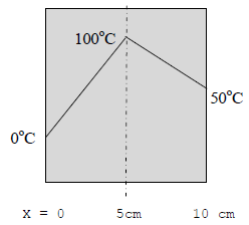

r = 0.1;
l = 10/100; % meters

We can get the initial temperature values if we express the left and right halves as linear equations. We will use $\Delta x=\frac{1}{100}$ meters.

delx = l/10;               % meters
s.t = zeros(1,l/delx + 1);  % note the + 1 --> need to include boundary temperatures
s.l = linspace(0,l,size(s.t, 2));
t.left = (100-0)/(l/2);
t.right = (50-100)/(l/2)

t = struct with fields:
     left: 2000
    right: -1000


s.t(1) = 0;
s.t(ceil(size(s.t, 2)/2)) = 100;
s.t(end) = 50;
for i = 2 : size(s.t, 2) - 1
    if i < ceil(size(s.t, 2) / 2)
    s.t(i) = t.left * s.l(i);
    elseif i > ceil(size(s.t, 2) / 2)
    s.t(i) = s.t(ceil(size(s.t, 2) / 2)) + (t.right * (s.l(i) - s.l(ceil(size(s.t, 2) / 2))));
    else
    disp("filled")
    end
end

filled


s.t;

Plot to verify

clf
fig1 = figure('Name','Initial Slab Temperature Profile');

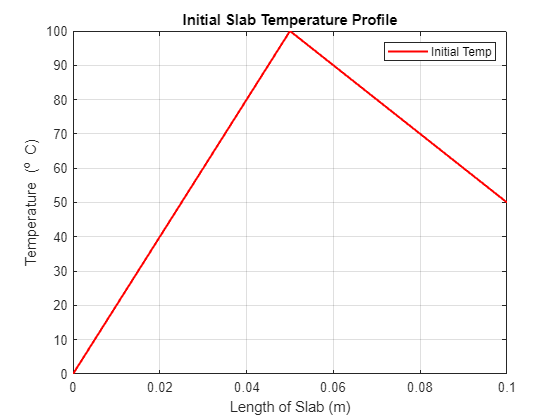

plot(s.l, s.t, LineWidth = 1.5, Color="r")
hold off
grid on
title('Initial Slab Temperature Profile')
xlabel('Length of Slab (m)')
ylabel('Temperature (^o C)')
legend('Initial Temp')

% xlim([0 0.1])
% ylim([-50 150])
ax1 = gca;

## 2. Numerical Solution (Explicit Method)

step = 10;
s.t(step + 1,1) = 0;
s.t(:,end) = 50;
for i = 2 : size(s.t, 2) - 1
    for j = 1 : step

        s.t(j+1,i) = s.t(j,i) + (r)*(s.t(j,i+1) - 2*s.t(j,i) + s.t(j,i-1));

    end
end
s.t

ans =          0   20.0000   40.0000   60.0000   80.0000  100.0000   90.0000   80.0000   70.0000   60.0000   50.0000
         0   20.0000   40.0000   60.0000   80.0000   97.0000   90.0000   80.0000   70.0000   60.0000   50.0000
         0   16.0000   34.0000   52.0000   70.0000   85.6000   81.7000   73.0000   64.0000   60.0000   50.0000
         0   12.8000   28.8000   45.0000   61.2000   75.4800   73.9200   66.5700   58.5000   59.4000   50.0000
         0   10.2400   24.3200   38.8800   53.4600   66.5040   66.6840   60.6480   53.4570   58.3700   50.0000
         0    8.1920   20.4800   33.5360   46.6560   58.5492   59.9976   55.1868   48.8304   57.0417   50.0000
         0    6.5536   17.2032   28.8768   40.6784   51.5050   53.8530   50.1492   44.5830   55.5164   50.0000
         0    5.2429   14.4179   24.8218   35.4304   45.2718   48.2329   45.5047   40.6813   53.8714   50.0000
         0    4.1943   12.0586   21.2992   30.8265   39.7605   43.1135   41.2270   37.0955   52.1653   50.

fig2 = figure('Name','Unsteady Slab Temperature Profile');

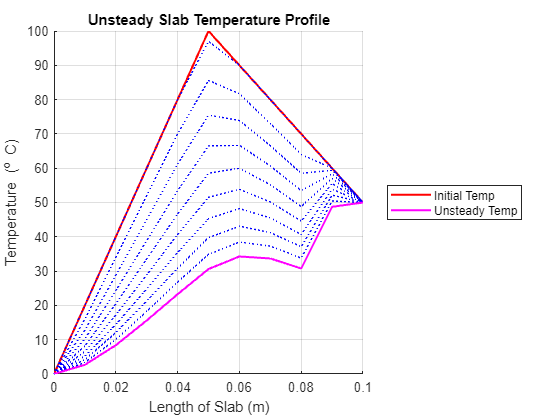

hold on
for i = 1 : size(s.t, 1)
    s.plot(i) = plot(s.l, s.t(i,:), LineWidth = 0.5, Color="b", LineStyle=":");
end

% alpha(s.plot(end), 0.1)
s.plot(1).LineStyle = "-";
s.plot(1).LineWidth = 1.5;
s.plot(1).Color = "r";
s.plot(end).LineStyle = "-";
s.plot(end).LineWidth = 1.5;
s.plot(end).Color = "magenta";

grid on
title('Unsteady Slab Temperature Profile')
xlabel('Length of Slab (m)')
ylabel('Temperature (^o C)')
legend([s.plot(1), s.plot(end)], {'Initial Temp', 'Unsteady Temp'}, Location="eastoutside")
hold off

% legend("Position", [0.44131,0.36746,0.42857,0.082143])
% xlim([0 0.1])
% ylim([-50 150])